clear all
close all
clc

pm_addunit('percent', 0.01, '1');
options = bodeoptions;
options.FreqUnits = 'Hz';
beep off

## pwm

fPWM_INV = 8e3;
dead_time_INV = 0;
dead_time = dead_time_INV;
delayINV_modA = 0;
pwm_out_lim = 1;


## simulink configuration

simlength = 1;

ts_inv = 1/fPWM_INV;
tsample = ts_inv;
ts_afe = ts_inv;

tc = ts_inv/200; % mandatory for stability of the solver

t_measure = simlength;
Nc = floor(t_measure/tc);
Ns_inv = floor(t_measure/ts_inv);
Ns_afe = floor(t_measure/ts_afe);
Nsample = floor(t_measure/tsample);
s=tf('s');
z=tf('z',ts_inv);

## grid settings

grid_emulator;

### FRT Settings

enable_frt = 0;

#### FRT, and other fault timing settings

test_index    = 25;
test_subindex = 4;

asymmetric_error_type = 0;  
% 0 -> Variant C, two phase, 
% 1 -> Variant D, single phase

start_time_grid_switch_open = 1e3;
start_time_LVRT = 2.0;
time_start_motor_control = 0.035;

time_aux_power_supply_fault = 1e3;
time_phase_fault = 1e3;
start_load = 0.25;

#### FRT gain factor for grid support

settle_time = 0.15;
k_frt_ref = 2;

#### Reactive current limits for grid support

i_grid_pos_eta_lim = 1;
i_grid_neg_xi_lim = 0.5;
i_grid_neg_eta_lim = 0.5;

#### Reactive current Limits - Red. Dyn. grid support

i_grid_pos_eta_red_lim = 0.1;
i_grid_neg_eta_red_lim = 0.1;
i_grid_neg_xi_red_lim = 0.1;

#### Grid voltage derivate implemented with double integrator observer

Aso = [0 1; 0 0];
Asod = eye(2) + Aso*ts_afe;
Cso = [1 0];
p2place = exp([-100 -500]*ts_afe);
Kd = (acker(Asod',Cso',p2place))';
l1 = Kd(1)

l1 = 0.0730

l2 = Kd(2)

l2 = 6.0210

#### Grid fault generator 

grid_fault_generator;

## simulink model variants

use_current_controller_from_simulink_module_1 = 0;
use_current_controller_from_ccaller_module_1 = 1 - use_current_controller_from_simulink_module_1;
use_gyro_model = 0;

## dimensioning

Pnom= 90e3;
Unom = 200;
Inom = Pnom/Unom/sqrt(3);
fnom = 400;
u_nom = 200/sqrt(3/2);
i_nom = sqrt(2)*Inom;
omega_nom = fnom*2*pi;
Imax_adc = i_nom*1.75;
CurrentQuantization = Imax_adc/2^11;
adc_quantizer = 1/2^11;

## DClink

CFi = 12.5e-3; %210e-6
Vdc_nom = 320;
Vdc_ref = 440;
Vdc = Vdc_nom*0.9;
Vdc_max = Vdc_nom*1.25;
udc_nom = Vdc_nom;

### Voltage sensor endscale, and quantization

Umax_adc = 1500;
VoltageQuantization = Umax_adc/2^11;

## General control settings

use_I_F_control = 0;
speed_mode = 0;
torque_mode = 1;
torque_ref = 350/i_nom*torque_mode;
angle_error_deg = 0;
angle_error = angle_error_deg/180*pi;
time_init = 0.025;
id_ref_pu = 0;
id_ff_omega_th = 0.2;
bemf_obsv_enable_speed = 0.20;

## I/F control

I_F_control = use_I_F_control;
iload_rms_ref = 0;
id_ref_if_pu = iload_rms_ref*sqrt(2)/i_nom;
omega_ref_if_pu = 400*2*pi/omega_nom;

## simulation data: speed reference, load torque

omega_m_nom = omega_nom;
omega_m_sim1 = omega_m_nom*0.2;
omega_m_sim2 = omega_m_nom*0.35;
omega_m_sim3 = omega_m_nom*0.5;
omega_m_sim4 = omega_m_nom*0.75;
omega_m_sim5 = omega_m_nom;

## double integrator observer

A = [0 1; 0 0];
Aso = eye(2) + A*ts_inv;
Cso = [1 0];
p2place = exp([-250 -1000]*1.75*ts_inv);
K = (acker(Aso',Cso',p2place))';
kg = K(1);
kw = K(2);
kalman_theta = kg;
kalman_omega = kw;

## kalman observer based on oscillator

f = 75;
w = 2*pi*f;
Ahn = [cos(w*ts_inv) sin(w*ts_inv); -sin(w*ts_inv) cos(w*ts_inv)];
Chn = [1 0];
Bhn = [0 0]';
sys_hn = ss(Ahn,Bhn,Chn,0);
% kalman filter parameters
q1kalman = 1;
q2kalman = 1;
Qkalman = [q1kalman 0; 0 q2kalman];
Rkalman = 1;

## high pass filter

omega_f = 2*pi*40;
delta_f = 0.7; 
lpf2q = (s^2 + 2*delta_f*omega_f*s + omega_f^2)\omega_f^2;
hpf2q = 1-lpf2q;
lpf2q_d = c2d(lpf2q,ts_inv);
hpf2q_d = c2d(hpf2q,ts_inv);
% figure; bode(lpf2q_d,hpf2q_d,options); grid on

## current control

kp_i = 0.5;
ki_i = 120;
kp_u = 0.5;
ki_u = 120;
kp_iq = kp_i;
ki_iq = ki_i;
kp_id = kp_i;
ki_id = ki_i;
CTRPIFF_CLIP_RELEASE = 0.001;

## current measure transfer function

fcut_cm = 48e3;
cm_tf = 1/(s/(2*pi*fcut_cm)+1);
cm_tfd = c2d(cm_tf,ts_inv);
% figure; bode(cm_tfd,options); grid on

## voltage filter

u_flt_fcut = 3600;
u_flt_g0 = u_flt_fcut * ts_inv * 2*pi;
u_flt_g1 = 1 - u_flt_g0;

## omega hat filter

omega_flt_fcut = 10;
omega_flt_g0 = omega_flt_fcut * ts_inv * 2*pi;
omega_flt_g1 = 1 - omega_flt_g0;

## reference filter

fcut_reference_flt = 4;
g0_reference_flt = fcut_reference_flt * ts_inv * 2*pi;
g1_reference_flt = 1 - g0_reference_flt;

## LCL switching filter

LFu1_AFE = 125e-6;
RLFu1_AFE = 157*0.05*LFu1_AFE;
LFu1_AFE_0 = LFu1_AFE;
RLFu1_AFE_0 = RLFu1_AFE/3;
% CFu = (60e-6);
CFu = (120e-6);
RCFu = (50e-3);

## output state and output transformer

P_trafo_out = 90e3;
I0_trafo_out = 2; % no load current
Vcc_perc_trafo_out = 4; %cc voltage percente
Vline1_trafo_out = 250; % primary voltage
Vline2_trafo_out = 200; % secondary voltage
Vphase1_trafo_out = Vline1_trafo_out/sqrt(3);
Vphase2_trafo_out = Vline2_trafo_out/sqrt(3);
freq_trafo_out = 400;
omega_trafo_out = freq_trafo_out*2*pi;
Inom_trafo_out = P_trafo_out/Vline2_trafo_out/sqrt(3);
Ld2_trafo_out = Vphase2_trafo_out/(100/Vcc_perc_trafo_out)/Inom_trafo_out/(omega_trafo_out); %leakage inductace
Rd2_trafo_out = 0.05*P_trafo_out/3/Inom_trafo_out^2; 
Lmu2_trafo_out= Vphase2_trafo_out/I0_trafo_out/(omega_trafo_out); %magentization inductance
Piron_trafo_out = 0.85e3;
Rm2_trafo_out = Vphase2_trafo_out^2/(Piron_trafo_out/3);
psi_trafo_out = Lmu2_trafo_out*I0_trafo_out*sqrt(2);

## RL load

R_RLload = 1;
L_RLload = 1e-6;
time_load_step = 0.5;

## IGBT and snubber data

Ron = 3.5e-3;
Csnubber = 0.15e-6;
Rsnubber = 2200;
Vgamma = 1.6;
i_swlosses_base_ff650r17ie4 = 650;
u_swlosses_base_ff650r17ie4 = 900;
eon_ff650r17ie4 = 0.3;
eoff_ff650r17ie4 = 0.205;
vcesat_ff650r17ie4 = 1.75;

### Settings for First Order Low Pass Filters

#### LPF 50Hz in state space (for initialization)

fcut = 50;
fof = 1/(s/(2*pi*fcut)+1);
[nfof, dfof] = tfdata(fof,'v');
[nfofd, dfofd]=tfdata(c2d(fof,ts_afe),'v');
fof_z = tf(nfofd,dfofd,ts_afe,'Variable','z');
[A,B,C,D] = tf2ss(nfofd,dfofd);
LVRT_flt_ss = ss(A,B,C,D,ts_afe);
[A,B,C,D] = tf2ss(nfof,dfof);
LVRT_flt_ss_c = ss(A,B,C,D);

#### LPF 161Hz

fcut_161Hz_flt = 161;
g0_161Hz = fcut_161Hz_flt * ts_afe * 2*pi;
g1_161Hz = 1 - g0_161Hz;

#### LPF 500Hz

fcut_500Hz_flt = 500;
g0_500Hz = fcut_500Hz_flt * ts_afe * 2*pi;
g1_500Hz = 1 - g0_500Hz;

#### LPF 75Hz

fcut_75Hz_flt = 75;
g0_75Hz = fcut_75Hz_flt * ts_afe * 2*pi;
g1_75Hz = 1 - g0_75Hz;

#### LPF 50Hz

fcut_50Hz_flt = 50;
g0_50Hz = fcut_50Hz_flt * ts_afe * 2*pi;
g1_50Hz = 1 - g0_50Hz;

#### LPF 10Hz

fcut_10Hz_flt = 10;
g0_10Hz = fcut_10Hz_flt * ts_afe * 2*pi;
g1_10Hz = 1 - g0_10Hz;

#### LPF 4Hz

fcut_4Hz_flt = 4;
g0_4Hz = fcut_4Hz_flt * ts_afe * 2*pi;
g1_4Hz = 1 - g0_4Hz;

#### LPF 1Hz

fcut_1Hz_flt = 1;
g0_1Hz = fcut_1Hz_flt * ts_afe * 2*pi;
g1_1Hz = 1 - g0_1Hz;

#### LPF 0.2Hz

fcut_0Hz2_flt = 0.2;
g0_0Hz2 = fcut_0Hz2_flt * ts_afe * 2*pi;
g1_0Hz2 = 1 - g0_0Hz2;

### Settings for RMS calculus

rms_perios = 1;
n1 = rms_perios/f_grid/ts_afe;
rms_perios = 10;
n10 = rms_perios/f_grid/ts_afe;

## Lithium Ion Battery

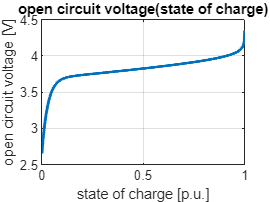

number_of_cells = 100; % nominal is 100

% stato of charge init
soc_init = 0.95; 

R = 8.3143;
F = 96487;
T = 273.15+40;
Q = 10; %Hr*A

Idc_nom = Pnom/Vdc_nom;
Rmax = Vdc_nom^2/(Pnom*0.1);
Rmin = Vdc_nom^2/(Pnom);

E_1 = -1.031;
E0 = 3.685;
% E0 = 3.485;
% E1 = 0.15;
E1 = 0.2156;
E2 = 0;
E3 = 0;
Elog = -0.05;
alpha = 35;

% R0 = 0.35;
% R1 = 0.35;
R0 = 0.15;
R1 = 0.15;
C1 = 0.1;
M = 125;


q1Kalman = ts_inv^2;
q2Kalman = ts_inv^1;
q3Kalman = 0;
rKalman = 1;

Zmodel = (0:1e-3:1);
ocv_model = E_1*exp(-Zmodel*alpha) + E0 + E1*Zmodel + E2*Zmodel.^2 +...
    E3*Zmodel.^3 + Elog*log(1-Zmodel+ts_inv);
figure; 
plot(Zmodel,ocv_model,'LineWidth',2);
xlabel('state of charge [p.u.]');
ylabel('open circuit voltage [V]');
title('open circuit voltage(state of charge)');
grid on

## C-Caller

open_system('ps_model');
Simulink.importExternalCTypes('ps_model','Names',{'mavgflt_output_t'});
Simulink.importExternalCTypes('ps_model','Names',{'dqvector_pi_output_t'});
Simulink.importExternalCTypes('ps_model','Names',{'sv_pwm_output_t'});